依赖[统一实验分析作图v18.0.0](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases)

命中错失PCA

[~,HitMissScore]=TransferLearning.UnifiedPcaModel(Paradigm="光声");

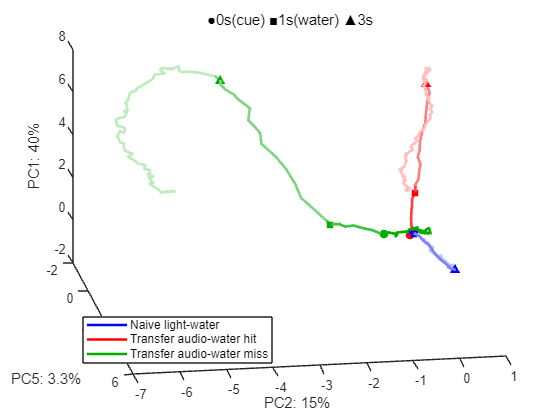

PCs=[5,2,1];
PcaScore=permute(HitMissScore.Score{PCs,:,["Naive_light_water","Transfer_hit","Transfer_miss"]},[3,1,2]);
LinesPC=table;
LinesPC.Points=PcaScore;
LinesPC.Color=GlobalOptimization.ColorAllocate(3,[1,1,1;1,1,1]);
Markers=table;
Markers.Index=[24;32;48];
Markers.Shape=('os^')';
figure;
Explained=HitMissScore.Explained(PCs);
Lines=UniExp.SegmentFadePlot(LinesPC,Markers,PatchArguments={'LineWidth',2});
UniExp.PcAxLabels(table(PCs',Explained,'VariableNames',["Index","Explained"],'RowNames',["X";"Y";"Z"]));
legend(Lines,["Naive light-water","Transfer audio-water hit","Transfer audio-water miss"],Interpreter='none',Location='southwest');
title('●0s(cue) ■1s(water) ▲3s');
view(90*(1-Explained(1)/(Explained(1)+Explained(2)*2)),90*(1-Explained(3)/sum(Explained)));
%3D无法生成矢量图，只能点阵
print(TransferLearning.ProjectPath('Fig1I.png'),'-dpng','-r200');